### Load the logged file

data=load("ModbusReceive.mat");


### Convert data to table

table=array2table(data.ans.Data,"VariableNames",["Reg_100","Reg_150","t_Unix"]);


### Convert unix time to datetime stamp

timestamp=datetime(table.t_Unix,'ConvertFrom','datenum','TicksPerSecond',1e3,'Format',' HH:mm:ss');


### Create a time series plot of logged data

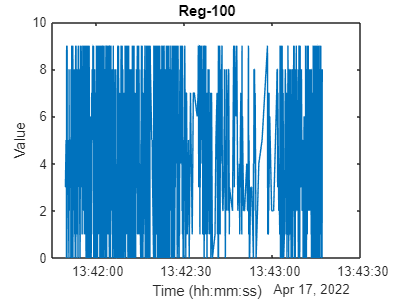

figure
plot(timestamp,table.Reg_100)
title("Reg-100")
ylabel("Value")
xlabel('Time (hh:mm:ss)')

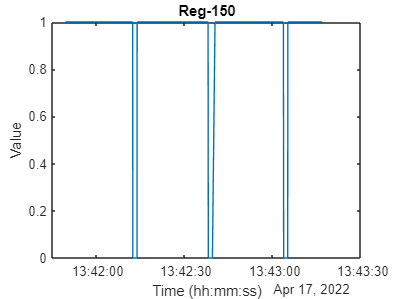

figure
% hold on
plot(timestamp,table.Reg_150)
title("Reg-150")
ylabel("Value")
xlabel('Time (hh:mm:ss)')